**Task 1: Co-occurence matrix (texture)**

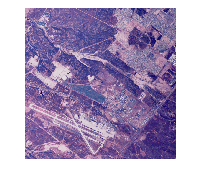

% task 1

% Read and display the image
f = imread('Test_1.tiff');
imshow(f);

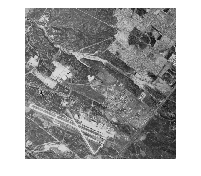

f = rgb2gray(f);
figure;
imshow(f);

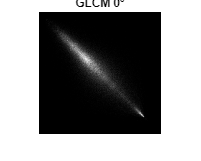


% Define offsets for different angles
D = 1; % You can change this to 2, 3, or 4 for different distances
offsets = [0 D; -D D; -D 0; -D -D];

% Calculate and display GLCMs for different angles
glcm_0 = graycomatrix(f, 'offset', offsets(1,:), 'NumLevels', 256, 'Symmetric', true);
glcm_45 = graycomatrix(f, 'offset', offsets(2,:), 'NumLevels', 256, 'Symmetric', true);
glcm_90 = graycomatrix(f, 'offset', offsets(3,:), 'NumLevels', 256, 'Symmetric', true);
glcm_135 = graycomatrix(f, 'offset', offsets(4,:), 'NumLevels', 256, 'Symmetric', true);

% Display GLCMs
figure;
imshow(glcm_0, []);
title('GLCM 0°');

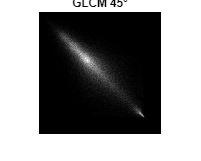


figure;
imshow(glcm_45, []);
title('GLCM 45°');

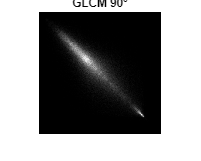


figure;
imshow(glcm_90, []);
title('GLCM 90°');

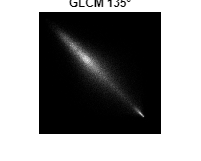


figure;
imshow(glcm_135, []);
title('GLCM 135°');

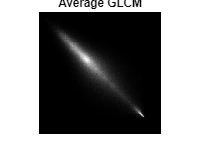


% Calculate the average GLCM
glcm_avg = (glcm_0 + glcm_45 + glcm_90 + glcm_135) / 4;
figure;
imshow(glcm_avg, []);
title('Average GLCM');


% Ensure GLCMs are integer-valued before passing to graycoprops
glcm_0 = uint32(glcm_0);
glcm_45 = uint32(glcm_45);
glcm_90 = uint32(glcm_90);
glcm_135 = uint32(glcm_135);
glcm_avg = uint32(glcm_avg);

% Estimate parameters for the co-occurrence matrices
stats_0 = graycoprops(glcm_0, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_45 = graycoprops(glcm_45, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_90 = graycoprops(glcm_90, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_135 = graycoprops(glcm_135, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_avg = graycoprops(glcm_avg, {'contrast', 'correlation', 'energy', 'homogeneity'});

% Display the estimated parameters
disp('GLCM 0° Stats:');

GLCM 0° Stats:


disp(stats_0);

       Contrast: 386.5209
    Correlation: 0.8859
         Energy: 1.3509e-04
    Homogeneity: 0.1677




disp('GLCM 45° Stats:');

GLCM 45° Stats:


disp(stats_45);

       Contrast: 635.4844
    Correlation: 0.8124
         Energy: 1.1000e-04
    Homogeneity: 0.1448




disp('GLCM 90° Stats:');

GLCM 90° Stats:


disp(stats_90);

       Contrast: 441.5751
    Correlation: 0.8697
         Energy: 1.2772e-04
    Homogeneity: 0.1611




disp('GLCM 135° Stats:');

GLCM 135° Stats:


disp(stats_135);

       Contrast: 480.2007
    Correlation: 0.8583
         Energy: 1.2179e-04
    Homogeneity: 0.1558




disp('Average GLCM Stats:');

Average GLCM Stats:


disp(stats_avg);

       Contrast: 491.8939
    Correlation: 0.8553
         Energy: 1.2086e-04
    Homogeneity: 0.1569



**Task 1: Additional Task: Rotate and Resize the Image**

% As an additional task, try to rotate and resize the input image, and rerun the above code. 
% Does orientation and/or image size have an effect?

%  Rotating and resizing the image can affect the texture measures. Here’s how you can test this:

%  Rotate the Image: Rotate the image by a certain angle (e.g., 45°) and recalculate the GLCMs and texture parameters.
% Rotate the image

fprintf('=================================')

fprintf('Task 1: Additional Task: Rotate and Resize the Image')

Task 1: Additional Task: Rotate and Resize the Image

fprintf('=================================')

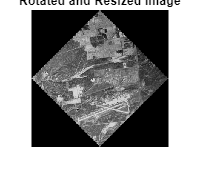



%  Rotate and Resize the Image: Resize the image to a different size (e.g., 50%) and recalculate the GLCMs and texture parameters.

f_rotated = imrotate(f, 45);
frr = imresize(f_rotated, 0.5); % Resize to 50% of rotated image size
figure;
imshow(frr);
title('Rotated and Resized Image');

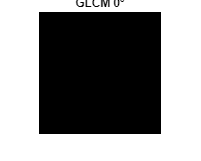



% Calculate and display GLCMs for different angles
glcm_0 = graycomatrix(frr, 'offset', offsets(1,:), 'NumLevels', 256, 'Symmetric', true);
glcm_45 = graycomatrix(frr, 'offset', offsets(2,:), 'NumLevels', 256, 'Symmetric', true);
glcm_90 = graycomatrix(frr, 'offset', offsets(3,:), 'NumLevels', 256, 'Symmetric', true);
glcm_135 = graycomatrix(frr, 'offset', offsets(4,:), 'NumLevels', 256, 'Symmetric', true);

% Display GLCMs
figure;
imshow(glcm_0, []);
title('GLCM 0°');

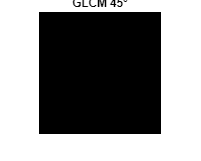


figure;
imshow(glcm_45, []);
title('GLCM 45°');

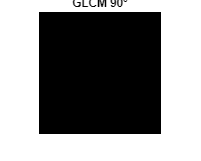


figure;
imshow(glcm_90, []);
title('GLCM 90°');

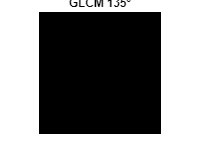


figure;
imshow(glcm_135, []);
title('GLCM 135°');

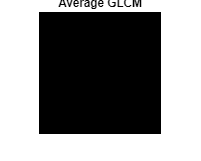


% Calculate the average GLCM
glcm_avg = (glcm_0 + glcm_45 + glcm_90 + glcm_135) / 4;
figure;
imshow(glcm_avg, []);
title('Average GLCM');


% Ensure GLCMs are integer-valued before passing to graycoprops
glcm_0 = uint32(glcm_0);
glcm_45 = uint32(glcm_45);
glcm_90 = uint32(glcm_90);
glcm_135 = uint32(glcm_135);
glcm_avg = uint32(glcm_avg);

% Estimate parameters for the co-occurrence matrices
stats_0 = graycoprops(glcm_0, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_45 = graycoprops(glcm_45, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_90 = graycoprops(glcm_90, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_135 = graycoprops(glcm_135, {'contrast', 'correlation', 'energy', 'homogeneity'});
stats_avg = graycoprops(glcm_avg, {'contrast', 'correlation', 'energy', 'homogeneity'});

% Display the estimated parameters
disp('GLCM 0° Stats:');

GLCM 0° Stats:


disp(stats_0);

       Contrast: 180.9892
    Correlation: 0.9778
         Energy: 0.2420
    Homogeneity: 0.5820




disp('GLCM 45° Stats:');

GLCM 45° Stats:


disp(stats_45);

       Contrast: 299.4372
    Correlation: 0.9632
         Energy: 0.2406
    Homogeneity: 0.5661




disp('GLCM 90° Stats:');

GLCM 90° Stats:


disp(stats_90);

       Contrast: 232.6943
    Correlation: 0.9714
         Energy: 0.2420
    Homogeneity: 0.5745




disp('GLCM 135° Stats:');

GLCM 135° Stats:


disp(stats_135);

       Contrast: 349.8893
    Correlation: 0.9570
         Energy: 0.2405
    Homogeneity: 0.5614




disp('Average GLCM Stats:');

Average GLCM Stats:


disp(stats_avg);

       Contrast: 269.0369
    Correlation: 0.9671
         Energy: 0.2367
    Homogeneity: 0.5664



**Task 2: Shape descriptors**

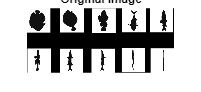

% task 2
% Step 1: Input the image
f = imread('shapes.png');
imshow(f);
title('Original Image');

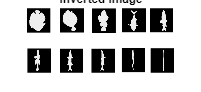


% Step 2: Invert the image
inverse_f = uint8(255) - f;
figure;
imshow(inverse_f);
title('Inverted Image');

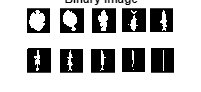


% Step 3: Threshold the image to obtain a proper black and white image
bw = imbinarize(inverse_f(:,:,1)); % Use only one channel for binarization
figure;
imshow(bw);
title('Binary Image');

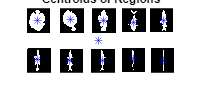


% Step 4: Calculate shape descriptors using regionprops
s = regionprops(bw, 'Area', 'Perimeter', 'Centroid', 'BoundingBox', 'ConvexHull', ...
    'Eccentricity', 'Orientation', 'MajorAxisLength', 'MinorAxisLength');

% Display the binary image with centroids marked
imshow(bw);
hold on;
centroids = cat(1, s.Centroid);
plot(centroids(:,1), centroids(:,2), 'b*');
title('Centroids of Regions');
hold off;


% Display the shape descriptors for each region
for k = 1:length(s)
    fprintf('Object %d:\n', k);
    fprintf('  Area: %f\n', s(k).Area);
    fprintf('  Perimeter: %f\n', s(k).Perimeter);
    fprintf('  Centroid: [%f, %f]\n', s(k).Centroid);
    fprintf('  BoundingBox: [%f, %f, %f, %f]\n', s(k).BoundingBox);
    fprintf('  Eccentricity: %f\n', s(k).Eccentricity);
    fprintf('  Orientation: %f\n', s(k).Orientation);
    fprintf('  MajorAxisLength: %f\n', s(k).MajorAxisLength);
    fprintf('  MinorAxisLength: %f\n', s(k).MinorAxisLength);
    fprintf('\n');
end

Object 1:


  Area: 36307.000000


  Perimeter: 2276.255000


  Centroid: [221.025973, 100.094445]


  BoundingBox: [0.500000, 0.500000, 452.000000, 199.000000]


  Eccentricity: 0.936790


  Orientation: -0.403505


  MajorAxisLength: 488.322326


  MinorAxisLength: 170.860583


Object 2:


  Area: 2256.000000


  Perimeter: 224.455000


  Centroid: [31.794326, 39.208333]


  BoundingBox: [6.500000, 7.500000, 51.000000, 63.000000]


  Eccentricity: 0.603834


  Orientation: 89.394671


  MajorAxisLength: 60.627755


  MinorAxisLength: 48.327009


Object 3:


  Area: 604.000000


  Perimeter: 173.665000


  Centroid: [33.125828, 159.847682]


  BoundingBox: [23.500000, 129.500000, 17.000000, 64.000000]


  Eccentricity: 0.971550


  Orientation: 88.305058


  MajorAxisLength: 62.365207


  MinorAxisLength: 14.770226


Object 4:


  Area: 1844.000000


  Perimeter: 189.405000


  Centroid: [133.400759, 36.291215]


  BoundingBox: [110.500000, 7.500000, 45.000000, 63.000000]


  Eccentricity: 0.735941


  Orientation: -67.010750


  MajorAxisLength: 60.653091


  MinorAxisLength: 41.064933


Object 5:


  Area: 533.000000


  Perimeter: 166.082000


  Centroid: [132.705441, 161.818011]


  BoundingBox: [123.500000, 129.500000, 19.000000, 63.000000]


  Eccentricity: 0.978298


  Orientation: 89.197501


  MajorAxisLength: 62.722802


  MinorAxisLength: 12.996251


Object 6:


  Area: 1230.000000


  Perimeter: 187.088000


  Centroid: [235.267480, 38.456911]


  BoundingBox: [217.500000, 7.500000, 33.000000, 63.000000]


  Eccentricity: 0.897950


  Orientation: -88.703052


  MajorAxisLength: 62.572292


  MinorAxisLength: 27.537922


Object 7:


  Area: 468.000000


  Perimeter: 153.907000


  Centroid: [233.170940, 161.500000]


  BoundingBox: [225.500000, 129.500000, 17.000000, 63.000000]


  Eccentricity: 0.983967


  Orientation: 89.070423


  MajorAxisLength: 63.665314


  MinorAxisLength: 11.354600


Object 8:


  Area: 735.000000


  Perimeter: 173.286000


  Centroid: [328.572789, 43.602721]


  BoundingBox: [312.500000, 7.500000, 28.000000, 63.000000]


  Eccentricity: 0.951450


  Orientation: 87.483751


  MajorAxisLength: 61.997820


  MinorAxisLength: 19.083215


Object 9:


  Area: 224.000000


  Perimeter: 126.243000


  Centroid: [326.544643, 154.888393]


  BoundingBox: [323.500000, 129.500000, 6.000000, 62.000000]


  Eccentricity: 0.995878


  Orientation: -89.016234


  MajorAxisLength: 63.052783


  MinorAxisLength: 5.719316


Object 10:


  Area: 736.000000


  Perimeter: 172.077000


  Centroid: [421.073370, 39.495924]


  BoundingBox: [408.500000, 7.500000, 24.000000, 63.000000]


  Eccentricity: 0.962284


  Orientation: -88.125539


  MajorAxisLength: 63.404590


  MinorAxisLength: 17.248918


Object 11:


  Area: 150.000000


  Perimeter: 125.432000


  Centroid: [420.533333, 160.613333]


  BoundingBox: [418.500000, 129.500000, 4.000000, 64.000000]


  Eccentricity: 0.998988


  Orientation: 89.210671


  MajorAxisLength: 70.748351


  MinorAxisLength: 3.182386
